# Classifying Traffic Sign Images

In this reading, you will prepare a traffic sign data set for classification and extracting predictor features. 

You will use these features and the Classification Learner App to train and evaluate a model that classifies traffic signs. When you have achieved a model with a test accuracy of at least 90%, you are ready to examine your results with the "Project: Classifying Traffic Sign Images" graded quiz on Coursera.

## Preparing Your Data

Create an image datastore from a folder of traffic signs. Labels are assigned based on the subfolder names, which correspond to the traffic sign type.

Make sure that you navigate to the **"Traffic Signs"** subfolder in the "Data" folder of the course download.

fileName = uigetdir;
imdsSigns = imageDatastore(fileName,"IncludeSubfolders",true,"LabelSource","foldernames");

### Split into Training and Test Sets

Create randomized training and test sets. 80% of the images should be assigned to the training set.

[imdsTrain,imdsTest] = splitEachLabel(imdsSigns,0.8,"randomized");

## Extracting Predictor Features

Now, use `bagOfFeatures` to create a set of predictor features. You will likely want to revisit this step several times with different parameters to get the best results. You will use these predictor features to train models to classify traffic signs.

For simplicity, we are only using `bagOfFeatures` for this project. However, in applications such as these, you can generally use everything you have learned so far in this course to create a set of predictor features, including hand-selected features, `bagOfFeatures`, or a combination of both. 

Recall that you are trying to create a table with one row for each image, a column for each feature, and an additional column for each image's label.

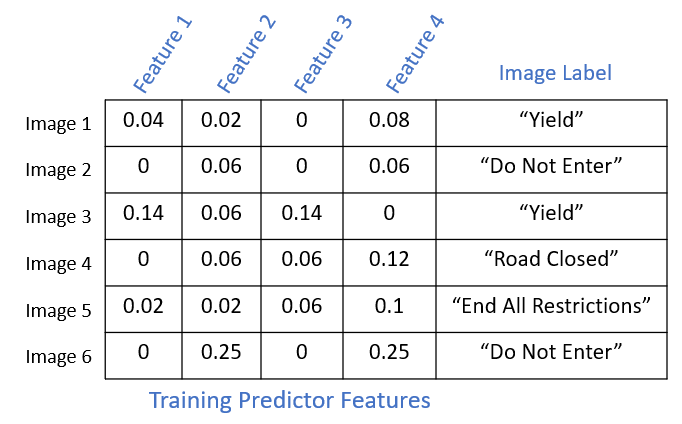

bag = bagOfFeatures(imdsTrain);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Do Not Enter
* Image category 2: End All Restrictions
* Image category 3: Road Closed
* Image category 4: Yield
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 768 images...done. Extracted 134404 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 1 has the least number of strongest features: 16186.
** Using the strongest 16186 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 64744
* Number of clusters          : 500
* Init

predFeatsTrain = encode(bag,imdsTrain);

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: Do Not Enter
* Image category 2: End All Restrictions
* Image category 3: Road Closed
* Image category 4: Yield
* Encoding 768 images...done.


featNames = "F" + string(1:500);
predTable = array2table(predFeatsTrain,"VariableNames",featNames);
predTable.Labels = categorical(imdsTrain.Labels);

Once you are satisfied with your predictor features, you also need to extract features from the test set. Remember to give the features the same names as the features in the training set.

predfeatstest = encode(bag,imdsTest);

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: Do Not Enter
* Image category 2: End All Restrictions
* Image category 3: Road Closed
* Image category 4: Yield
* Encoding 192 images...done.


newTable = array2table(predfeatstest,"VariableNames",featNames);
newTable.Labels = categorical(imdsTest.Labels)

newTable = 192×501 table
    F1       F2       F3      F4       F5       F6          F7          F8       F9      F10         F11       F12     F13       F14         F15      F16    F17    F18    F19      F20         F21         F22       F23      F24         F25      F26      F27         F28       F29      F30       F31        F32       F33    F34      F35       F36     F37

## Training Models

Train classification models using the Classification Learner App and the predictor features you have just created. Your goal is to train a model with a test accuracy of **at least 90%**.

Make sure you save your Classification Learner App session. You will want to revisit it as you take the graded quiz associated with this project.

*Copyright 2022 The MathWorks, Inc.*